**Генерация функций с сохранением в отдельный файл для оптимизации критерия стабильности **

Кривая равновесия (f_1 = 0)

clear all;

syms a b c l_1 l_2 psi theta_2 theta_2i k_2i
f = h(a,b,c,l_1,psi,theta_2)*cos(theta_2);
matlabFunction(f,'File','equilibriumCurve');

Генерация целевой функции для поиска Paradoxical point в символьной форме

clear all;
syms k_2 theta_2 k_2i theta_2i a b c l_1 psi;

f_1 = equilibriumCurve(a, b, c, l_1, psi, theta_2); % k_2 = f(theta_2)
f_2 = solve(singlePointContactTrajectory(k_2, theta_2, k_2i, theta_2i, l_1), k_2); % k_2 = f(theta_2)
f_2 = f_2(2);

f_1d = diff(f_1, theta_2);
f_2d = diff(f_2, theta_2);

% Условие касания двух кривых: значения кривых совпадают в точке касания и
% производные в точке касания равны
F1 = f_1 - f_2;
F2 = f_1d - f_2d;

% Условие, что точка касания точно принадлежит кривой
F3 = k_2 - f_2;

f = [F1; F2; F3];

matlabFunction(f,'File','objParadoxical');

Определение координат Paradoxical point

clear all;

a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

paradoxicalCoord(a, b, c, l_1, psi)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =     0.3514    0.3608    0.3346    0.0000


Определение критерия стабильности для заданной геометрии пальца

clear all;

a = 1.8162; b = 6.4299; c = 2.3660;
l_1 = 4; l_2 = l_1;
psi = pi/2;
    
stabilityCriterion(a, b, c, l_1, l_2, psi)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 1.4981

Постановка задачи оптимизации геометрии пальца с целью максимизации критерия стабильности

clear all;

l_1 = 1.0; l_2 = l_1; psi = pi/2;
b = 1.0; c = 1/3;

% Оптимизация на основе Problem-based approach
a = optimvar('a', 'LowerBound', 0.2, 'UpperBound', 2);
% b = optimvar('b', 'LowerBound', 1, 'UpperBound', 9);
% c = optimvar('c', 'LowerBound', 1, 'UpperBound', 2.5);

% Конвертация функции подсчета критерия стабильности в формат целевой функции для оптимизации
obj = fcn2optimexpr(@(a)stabilityCriterion(a, b, c, l_1, l_2, psi), a);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


prob = optimproblem("Objective", obj);

% Начальные условия
x0.a = a.LowerBound + (a.UpperBound-a.LowerBound)*rand()

x0 = struct with fields:
    a: 0.4799


% x0.b = 6;
% x0.c = 1.5;

% Ограничения
% bfun = fcn2optimexpr(@(a)max(equilibriumCurve(a,b,c,l_1,psi,linspace(0,pi/2,20))),a);
% bfun2 = fcn2optimexpr(@(a)isreal(equilibriumCurve(a,b,c,l_1,psi,linspace(0,pi/2,20))),a);
bfun = 4*a^2*b^2-(l_1*(l_1+2*c)-a^2-b^2+c^2)^2;

prob.Constraints.cons1 = bfun >= 0;
% prob.Constraints.cons2 = bfun <= l_2;

% Решение с помощью fmincon
% options = optimoptions('fmincon', 'Display', 'iter', 'MaxFunctionEvaluations',6e+5);

% tic
% [sol, fval] = fmincon(prob, x0, [], [], [], [], [], [], [], options)
% [sol, fval] = solve(prob, x0, 'Options', options) 
% toc

% Решение с помощью GA на основе Problem-based Approach с
% распараллеливанием вычислений
parpool

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 4
              Cluster: 

Solving problem using ga.

Single objective optimization:
1 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the f

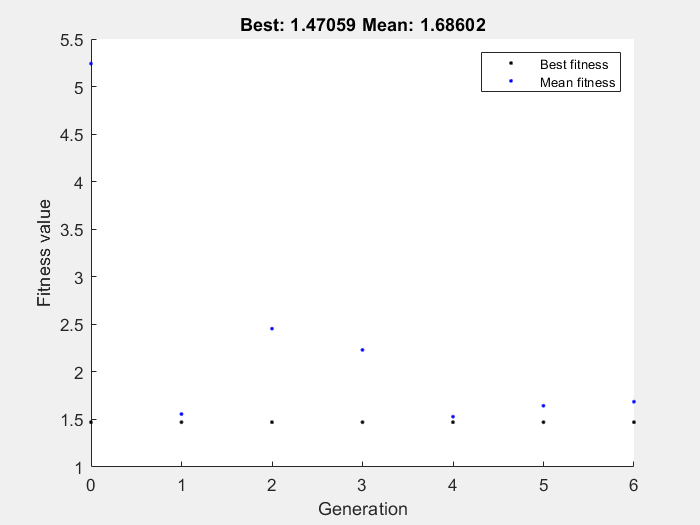

options = optimoptions(@ga,...
    'PlotFcn',{@gaplotbestf},...
    'Display','iter');
options = optimoptions(options, 'MaxGenerations', 10, 'MaxStallGenerations', 10, 'PopulationSize', 25, 'UseParallel', true);
% options.PopulationSize = 20;

rng default % For reproducibility
tic
[sol,fval] = solve(prob,"Solver","ga", 'Options',options);

toc

Elapsed time is 50.884755 seconds.


% delete(gcp('noncreate')); % Для завершения узла паралельных вычислений

theta_2_set = linspace(0,pi/2,20);
for a=linspace(0.1,0.9,10)
   k_2 =  equilibriumCurve(a,b,c,l_1,psi, theta_2_set);
    if isreal(k_2)
        k_2
    end
end